root_folder = "/home/akamath/Documents/deep-planner/data/resized";

n_subjects = 100;

target_name = "Target";

brain_name = "Brain";


for subject = 1:n_subjects
    try
        subject_name = "DLDP_" + num2str(subject, '%03d');
        subject_path = root_folder + filesep + subject_name;
    
        target_volume = niftiread(subject_path + filesep + target_name + "_resized.nii.gz");
        brain_volume = niftiread(subject_path + filesep + brain_name + "_resized.nii.gz");
        
        relative_size = sum(target_volume(:) == 1) / sum(brain_volume(:) == 1);
    
        disp("Relative target size for subject: " + string(subject) + " is: " + string(relative_size));
    catch
        disp("Something went wrong!");
    end

end

Relative target size for subject: 1 is: 0.067195
Relative target size for subject: 2 is: 0.059378
Relative target size for subject: 3 is: 0.080833
Relative target size for subject: 4 is: 0.031484
Relative target size for subject: 5 is: 0.15246
Relative target size for subject: 6 is: 0.014636
Relative target size for subject: 7 is: 0.023069
Relative target size for subject: 8 is: 0.066747
Relative target size for subject: 9 is: 0.051651
Relative target size for subject: 10 is: 0.13278
Relative target size for subject: 11 is: 0.15268
Relative target size for subject: 12 is: 0.14074
Relative target size for subject: 13 is: 0.16816
Relative target size for subject: 14 is: 0.07942
Relative target size for subject: 15 is: 0.008032
Relative target size for subject: 16 is: 0.059294
Relative target size for subject: 17 is: 0.058146
Relative target size for subject: 18 is: 0.078872
Relative target size for subject: 19 is: 0.098927
Relative target size for subject: 20 is: 0.15363
Relative target 

Something went wrong!


Relative target size for subject: 41 is: 0.12185
Relative target size for subject: 42 is: 0.1643
Relative target size for subject: 43 is: 0.095983
Relative target size for subject: 44 is: 0.1026
Relative target size for subject: 45 is: 0.051343
Relative target size for subject: 46 is: 0.062961
Relative target size for subject: 47 is: 0.084701
Relative target size for subject: 48 is: 0.048254
Relative target size for subject: 49 is: 0.041362
Relative target size for subject: 50 is: 0.125
Relative target size for subject: 51 is: 0.10164
Relative target size for subject: 52 is: 0.078162
Relative target size for subject: 53 is: 0.058129
Relative target size for subject: 54 is: 0.029148
Relative target size for subject: 55 is: 0.062321
Relative target size for subject: 56 is: 0.068539
Relative target size for subject: 57 is: 0.074559
Relative target size for subject: 58 is: 0.0211
Relative target size for subject: 59 is: 0.10708
Relative target size for subject: 60 is: 0.12384
Relative targ

Something went wrong!


Relative target size for subject: 64 is: 0.07628


Something went wrong!


Relative target size for subject: 66 is: 0.032402


Something went wrong!


Relative target size for subject: 68 is: 0.12413
Relative target size for subject: 69 is: 0.014487
Relative target size for subject: 70 is: 0.070889
Relative target size for subject: 71 is: 0.10048
Relative target size for subject: 72 is: 0.077916
Relative target size for subject: 73 is: 0.016395
Relative target size for subject: 74 is: 0.049287
Relative target size for subject: 75 is: 0.10306
Relative target size for subject: 76 is: 0.016923


Something went wrong!


Relative target size for subject: 78 is: 0.054345
Relative target size for subject: 79 is: 0.027808
Relative target size for subject: 80 is: 0.024775
Relative target size for subject: 81 is: 0.075516
Relative target size for subject: 82 is: 0.012293
Relative target size for subject: 83 is: 0.13435
Relative target size for subject: 84 is: 0.03229
Relative target size for subject: 85 is: 0.077551
Relative target size for subject: 86 is: 0.2293
Relative target size for subject: 87 is: 0.060047
Relative target size for subject: 88 is: 0.10329
Relative target size for subject: 89 is: 0.026333
Relative target size for subject: 90 is: 0.027188
Relative target size for subject: 91 is: 0.10042
Relative target size for subject: 92 is: 0.080547
Relative target size for subject: 93 is: 0.072099
Relative target size for subject: 94 is: 0.082106
Relative target size for subject: 95 is: 0.065433
Relative target size for subject: 96 is: 0.028375
Relative target size for subject: 97 is: 0.14382
Relativ

oar_names = ["BrainStem", "Chiasm", "Cochlea_L", "Cochlea_R", ...
             "Eye_L", "Eye_R", "Hippocampus_L", "Hippocampus_R", ...
             "LacrimalGland_L", "LacrimalGland_R", ...
             "OpticNerve_L", "OpticNerve_R", "Pituitary"];

T = table('size', [n_subjects, size(oar_names, 2)], 'VariableTypes', repmat("double", size(oar_names)), 'VariableNames', oar_names);

for subject = 1:n_subjects
    try
        subject_name = "DLDP_" + num2str(subject, '%03d');
        subject_path = root_folder + filesep + subject_name;
    
        target_volume = niftiread(subject_path + filesep + target_name + "_resized.nii.gz");
        brain_volume = niftiread(subject_path + filesep + brain_name + "_resized.nii.gz");
        
        relative_size = sum(target_volume(:) == 1) / sum(brain_volume(:) == 1);
    
        %disp("Relative target size for subject: " + string(subject) + " is: " + string(relative_size));

        target_dist = bwdist(target_volume);

        for structure = oar_names
            structure_volume = niftiread(subject_path + filesep + structure + "_resized.nii.gz");

            min_dist = min(target_dist(structure_volume(:) == 1), [], 'all');

            %disp("Minimum distance between: " + string(oar) + " and target is: " + string(min_dist));
            T{subject, structure} = min_dist;
        end

    catch
        disp("Something went wrong!");
        T{subject, :} = nan(size(T{subject, :}));
    end

end

Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!


writetable(T, "minimum_distance_to_target_post_change.xlsx");

structure_names = oar_names;
structure_names(end + 1) = "Target";

rel_size_table = table('size', [n_subjects, size(structure_names, 2)], 'VariableTypes', repmat("double", size(structure_names)), 'VariableNames', structure_names);

for subject = 1:n_subjects
    try
        subject_name = "DLDP_" + num2str(subject, '%03d');
        subject_path = root_folder + filesep + subject_name;
    
        target_volume = niftiread(subject_path + filesep + target_name + "_resized.nii.gz");
        brain_volume = niftiread(subject_path + filesep + brain_name + "_resized.nii.gz");
    
        %disp("Relative target size for subject: " + string(subject) + "
        %is: " + string(relative_size));

        for structure = structure_names
            structure_volume = niftiread(subject_path + filesep + structure + "_resized.nii.gz");

            relative_size = sum(structure_volume(:) == 1) / sum(brain_volume(:) == 1);

            %disp("Minimum distance between: " + string(oar) + " and target is: " + string(min_dist));
            rel_size_table{subject, structure} = relative_size;
        end

    catch
        disp("Something went wrong!");
        rel_size_table{subject, :} = nan(size(rel_size_table{subject, :}));
    end

end

Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!



writetable(rel_size_table, "relative_size_of_structure_post_change.xlsx");

structure = structure_names(2);
edges = linspace(min(rel_size_table{:, structure}), max(rel_size_table{:, structure}), 100);
mean_size = nanmean(rel_size_table{:, structure});
std_size = nanstd(rel_size_table{:, structure});

histogram(rel_size_table{2:end, structure}, edges)

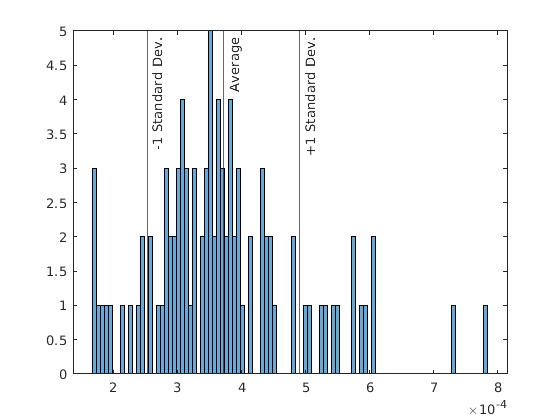

hold on
xline([mean_size-std_size mean_size mean_size+std_size],'-',{'-1 Standard Dev.','Average','+1 Standard Dev.'})
hold off

surface_area_table = table('size', [n_subjects, size(structure_names, 2)], 'VariableTypes', repmat("double", size(structure_names)), 'VariableNames', structure_names);
solidity_table = table('size', [n_subjects, size(structure_names, 2)], 'VariableTypes', repmat("double", size(structure_names)), 'VariableNames', structure_names);

for subject = 1:n_subjects
    try
        subject_name = "DLDP_" + num2str(subject, '%03d');
        subject_path = root_folder + filesep + subject_name;

        for structure = structure_names
            structure_volume = niftiread(subject_path + filesep + structure + "_resized.nii.gz");

            s = regionprops3(structure_volume,"SurfaceArea","Solidity");

            %disp("Minimum distance between: " + string(oar) + " and target is: " + string(min_dist));
            surface_area_table{subject, structure} = s.SurfaceArea;
            solidity_table{subject, structure} = s.Solidity;
        end

    catch
        disp("Something went wrong!");
        surface_area_table{subject, :} = nan(size(surface_area_table{subject, :}));
        solidity_table{subject, :} = nan(size(solidity_table{subject, :}));
    end

end

Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!
Something went wrong!


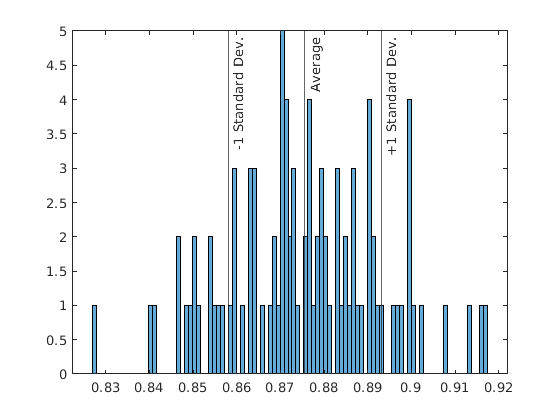

structure = structure_names(6);
property = "solidity_table";

if property == "surface_area_table"
    data_table = surface_area_table;
else
    data_table = solidity_table;
end

edges = linspace(min(data_table{:, structure}), max(data_table{:, structure}), 100);
mean_size = nanmean(data_table{:, structure});
std_size = nanstd(data_table{:, structure});

histogram(data_table{2:end, structure}, edges)
hold on
xline([mean_size-std_size mean_size mean_size+std_size],'-',{'-1 Standard Dev.','Average','+1 Standard Dev.'})
hold off